# Luenberger (Pole Placement) Observer Design

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

In the previous lesson, we have seen how the[ observability](matlab:open('./L01_IntroductiontoStateEstimation.mlx')) of a given process can be assessed. The focus was to estimate the initial state. For implementation of a state feedback controller, we need to generate the state estimate at each sampling instant. In this lesson, we will understand the basics of online recursive estimation of states by merging measured data and predictions of dynamic  model. The requirement of observability is still central to the method of this lesson. Once the system is found to be observable, we can design an observer for the system, which can recursively estimate the states of the system. 

**Learning Objectives:**

- To understand the basics of online recursive estimation of states by combining measured data and model predictions

- To study fundamentals of pole placement design (Luenberger Observer) 

- Understand differences between prediction estimation and current state estimation 

## Open-Loop State Observer

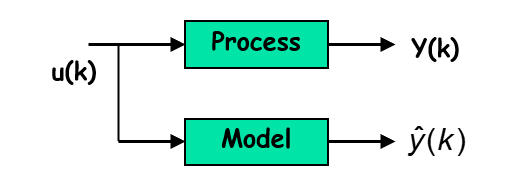

**Figure 1:** **Open-loop Observer    **

Let the *true process or system dynamics* be given as,

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$--------------(1)

$y\left(k\right)=\textrm{Cx}\left(k\right)$ ------(2)

Since we assume that the state-space matrices are known, one can build an **Open-Loop Observer/State Estimator** by using the model equations recursively. The trouble is that we do not know the true initial condition $x\left(0\right)\ldotp$So to use the model as a state estimator, we need to start from an initial guess $\hat{x} \left(0\right)\not= x\left(0\right)$ and use the model as follows 

$\widehat{x} \left(k+1\right)=\Phi \widehat{x} \left(k\right)+\Gamma u\left(k\right)\;\;\textrm{for}\;k=0,1,2,\ldotp \ldotp \ldotp \ldotp \ldotp$ ----(3)


$$\hat{x} \left(k+1\right)=\Phi \hat{x} \left(k\right)+\Gamma u\left(k\right)$$


Note that the hat symbol '$\hat{}$' distinguishes the plant states and measurements from those of the model. We call the above estimator "Open-Loop" since the plant measurement $y\left(k\right)$ is not used in making the model predictions in Eq (2). Let us define the state estimation error as

$\varepsilon \left(k\right)=x\left(k\right)-\widehat{x} \left(k\right)$     ----------(4)

Subtracting equation (3) from equation (1), the estimation error evolves as 

$\varepsilon \left(k+1\right)=\Phi \varepsilon \left(k\right)\Rightarrow \varepsilon \left(k\right)=\Phi^k \varepsilon \left(0\right)$   ------------(5)

If the system is asymptotically stable, i.e., all eigenvalues $\lambda_i$ of $\Phi$ strictly lie inside the unit circle or $\max_i \;|\lambda_i |=\rho \left(\Phi \right)<1$, then $\|\varepsilon \left(k\right)\|\to 0\;\textrm{as}\;k\to \infty$.

There are two difficulties with the open loop state estimator: 

- The above discussed estimator cannot be used If process is marginally stable or unstable.

-  Even when $\rho \left(\Phi \right)<1$,$\rho \left(\Phi \right)$ decides rate of convergence of  $\varepsilon \left(k\right)$. 

Can we accelerate this convergence? The answer is yes. The rate of convergence of  $\varepsilon \left(k\right)$ can be improved using a **closed Loop estimator**, discussed in the next section.

## Closed Loop Observer with Measurement Feedback 

Figure 2 below shows the schematic of a closed loop observer. Here the concept of output / measurement feedback is used to develop a **recursive state estimator with measurement feedback.**

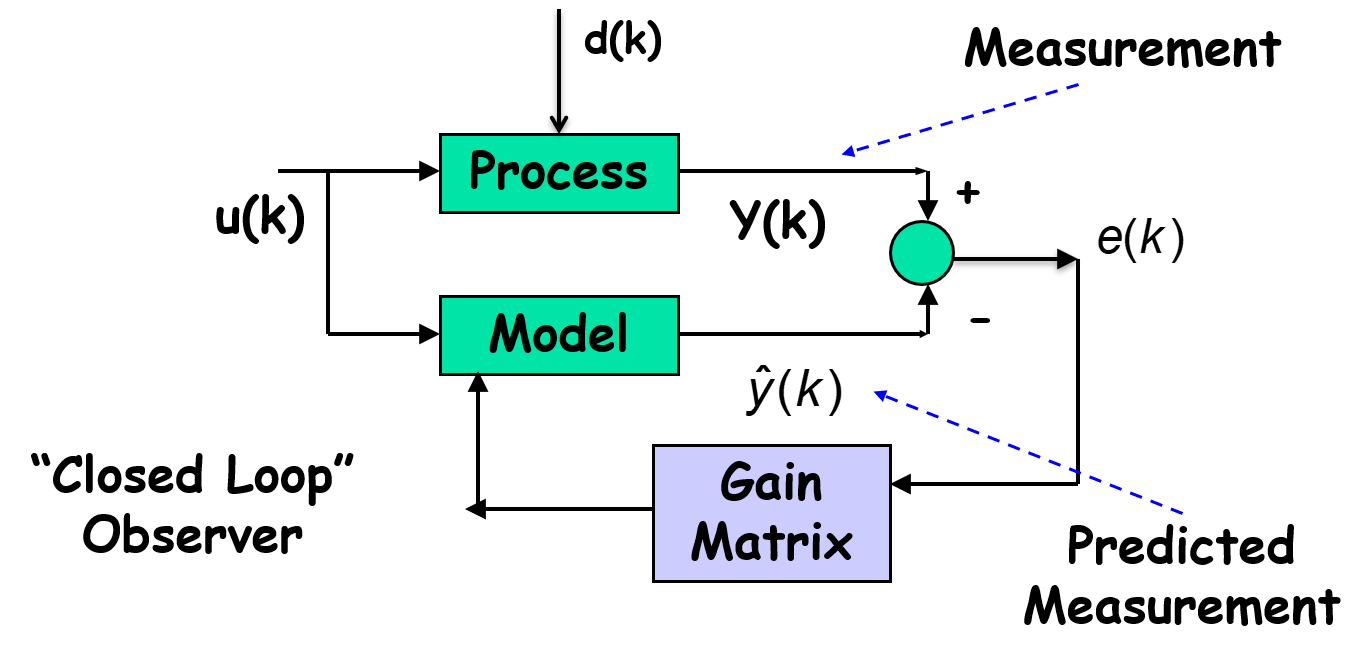

**Figure 2: Closed Loop Observer**

Let the true process dynamics be given as in equation 1. Unlike the open-loop estimator, here we use **measurement innovation** $e\left(k\right)$

$e\left(k\right)=y\left(k\right)-\hat{y} \left(k\right)=y\left(k\right)-\textrm{Cx}̂\left(k\right)$---------(6)

  to estimate the plant states by adding a correction term to the open-loop observer. Thus, the modified recursive estimator can be represented a

$\hat{x} \left(k+1\right)=\Phi \hat{x} \left(k\right)+\Gamma u\left(k\right)+L\;e\left(k\right)$--------------(7)

where  $L$ represents a $n\times r$ observer gain matrix.  Subtracting observer dynamics (5) from the plant dynamics (1), we arrive at 

$\varepsilon \left(k+1\right)=\Phi \varepsilon \left(k\right)-L\;e\left(k\right)$   ----------(8)

where $e\left(k\right)$ is given as

$e\left(k\right)=y\left(k\right)-\hat{y} \left(k|k-1\right)=y\left(k\right)-C\hat{\mathrm{x}} \left(k|k-1\right)$.  -----------(9)

Substituting for $e\left(k\right)$ in equation 8 we get the state estimation error dynamics equation,

$\varepsilon \left(k+1\right)=\left(\Phi -L\;C\right)\varepsilon \left(k\right)$  --------(10)

Thus, we have an additional handle to influence the estimation error dynamics. The primary requirement is $\|\varepsilon \left(k\right)\|\to 0\;\textrm{as}\;k\to \infty$. This can be achieved by choosing L matrix such that $\rho \left(\Phi -\textrm{LC}\right)<1$. In fact, for a asymptotically stable system, if we select L matrix such that $\rho \left(\Phi -\textrm{LC}\right)<\rho \left(\Phi \right)$ then the estimation error can approach the origin faster. 

### **Luenberger Observer Design**

 Now the question is** how to choose estimator gain matrix **$L$** such that estimation error reduces to zero as quickly as possible?  **Moreover, when system dynamics evolves as 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d d\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)+v\left(k\right)\\
x\left(0\right):\textrm{Initial}\;\textrm{Condition}\;
\end{array}$ -------(11)

the estimation error dynamics changes to 

$\varepsilon \left(k+1\right)=\left(\Phi -L\;C\right)\varepsilon \left(k\right)+\Gamma_d d\left(k\right)+L\;v\left(k\right)$   ---------(12)

To simplify the notations, let us define matrix $\Phi_{\textrm{CL}} =\left(\Phi -L\;C\right)$ and express 

$\varepsilon \left(k+1\right)={\left(\Phi_{\textrm{CL}} \right)}^k \varepsilon \left(0\right)+C{\left(\Phi_{\textrm{CL}} \right)}^{k-1} \Gamma_d d\left(0\right)+\ldotp \ldotp \ldotp \ldotp +C\Gamma_d d\left(k-1\right)+{\left(\Phi_{\textrm{CL}} \right)}^{k-1} L\;v\left(0\right)+\ldotp \ldotp \ldotp \ldotp +L\;v\left(k-1\right)$  ------(13)

Thus, choice of *L* matrix not only determines the rate at which the initial error decays to zero but also determines the sensitivity of the estimation error to unmeasured disturbances and measurement noise. As a consequence, choice of *L *plays an important role in closed loop performance of a state feedback controller. 

The primary design condition is to Choose $L$ such that  $\rho \left(\Phi -L\;C\right)<1$, i.e. all the closed loop poles lie strictly inside the unit circle. A popular approach to design an estimator is by pole placement, which can be summarized as follows:

**Step 1: **Select the **desired locations of eigenvalues** of $\left(\Phi -L\;C\right)$, say $\lambda_i =p_i :i=1,2,\ldotp \ldotp \ldotp ,n$ and construct polynomial 

$\left(\lambda -p_1 \right)\left(\lambda -p_2 \right)\ldotp \ldotp \ldotp \ldotp \ldotp \left(\lambda -p_n \right)=\lambda^n +b_1 \lambda^{n-1} +\ldotp \ldotp \ldotp \ldotp +b_n =0$ ------(14)

**Step 2: **Find the characteristic equation of $\left(\Phi -L\;C\right)$ in terms of elements of matrix *L, i.e. *

$\det \left(\Phi -L\;C\right)=\lambda^n +a_1 {\left(L\right)\lambda }^{n-1} +\ldotp \ldotp \ldotp \ldotp +a_n \left(L\right)=0$ ------(15)

Here, notation $a_i \left(L\right)$ indicates dependence of the polynomial coefficients on elements of matrix L. 

**Step 3:** Select elements of $L$ such that the following *n* conditions hold 

$a_1 \left(L\right)=b_1 ,a_2 \left(L\right)=b_2 ,\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp ,a_n \left(L\right)=b_n$  ------(16)

Here we consider two scenarios: 

**Single Output Systems: **In this case $L$ is $n\times 1$ vector consisting of $n$ unknowns $l_1 ,l_2 ,\ldotp \ldotp \ldotp \ldotp ,l_n$ and constraints (14) lead to n equations in n unknown

$\begin{array}{l}
a_1 \left(l_1 ,l_2 ,\ldotp \ldotp \ldotp \ldotp ,l_n \right)=b_1 \\
a_2 \left(l_1 ,l_2 ,\ldotp \ldotp \ldotp \ldotp ,l_n \right)=b_2 \\
\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \\
a_n \left(l_1 ,l_2 ,\ldotp \ldotp \ldotp \ldotp ,l_n \right)=b_n 
\end{array}$  ------(17)

It can be shown that, if the system is observable, then there is a unique solution to this set of equations. 

**Multiple Output Systems: **In this case $L$ is $n\times r$ matrix consisting of $n\times r$ unknowns $l_{11} ,l_{12} ,\ldotp \ldotp \ldotp \ldotp ,l_{\textrm{nr}}$

$\begin{array}{l}
a_1 \left(l_{11} ,l_{12} ,\ldotp \ldotp \ldotp \ldotp ,l_{\textrm{nr}} \right)=b_1 \\
a_2 \left(l_{11} ,l_{12} ,\ldotp \ldotp \ldotp \ldotp ,l_{\textrm{nr}} \right)=b_2 \\
\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \\
a_n \left(l_{11} ,l_{12} ,\ldotp \ldotp \ldotp \ldotp ,l_{\textrm{nr}} \right)=b_n 
\end{array}$  ------(18) 

The trouble here is that we have less equations than the number of unknowns and we need to introduce additional constraints to arrive at a solution. There are many ways to introduce additional constraints an a more detailed discussion can be found in Fadali and Visioli (2019). We leave this part as a self-reading exercise for the reader. 

State estimators designed by pole placement approach are referred to as Luenberger observer. Note that MATLAB Control System Toolbox has function ***place ***that allows us to place poles. Here we demonstrate efficacy of pole placement estimator. 

clear all

**Task 1: **On selecting the operating point, corresponding steady state linear discrete model and parameters will be loaded in the workspace. Specify Operating Point,  Minimum Phase or Nonminimum Phase

operating_pt=1;

% Load quadruple tank parameters and steady state The following file loads QTank data structre 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
 QTank.Q_mat=0.0025*eye(2);
end

phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = QTank.C_mat ; 

[n_st,n_ip] = size(gam);
[n_op, nx] = size(C_mat) ;
[nx, n_d] = size(gam_d)  ; 
samp_T = 4 ;  

**Task 2 :** Select the values of closed loop observer poles in the range 0 to 1. 

p1=0.5;
p2=0.6;
p3=0.75;
p4=0.65;
obs_poles = [ p1 p2 p3 p4]'; % Error Dynamics Poles 

Observer gain matrix Lp_mat, is obtained using **place command** in matlab. 

[**K = place(A,B,P)** ](https://in.mathworks.com/help/control/ref/place.html)computes a state-feedback matrix K such that the eigenvalues of A-B*K are those specified in the vector P.

Note that this function is written for controller design problem, i.e. placement of eigenvalues of matrix $\left(\Phi -\Gamma G\right)$ where $u\left(k\right)=-\textrm{Gx}\left(k\right)$ is a state feedback control law. Thus, to use it for observer design, we need to place eigenvalues of matrix $\left(\Phi^T -C^T {\mathrm{L}}^T \right)$, which, are identical to eigenvalues of $\left(\Phi -L\;C\right)$. 

Lp_mat= place(phy', C_mat', obs_poles)  ;
disp('Gain of Closed Loop Observer is')

Gain of Closed Loop Observer is


Lp_mat = Lp_mat' 

Lp_mat =     0.7845         0
         0    1.5092
    0.2892         0
         0    2.2720


**Task 3:** Let's now see the closed loop **eigen values of (phy -  Lp_mat * C_mat )** i. e. $\Phi -\textrm{LC}$ using eig command in MATLAB and compare with open loop 

EigVal_CL = eig( phy -  Lp_mat * C_mat ) ; 
EigVal_CL'

ans =     0.6500    0.7500    0.5000    0.6000


disp('Open loop eigen values:eigen values of phy')

Open loop eigen values:eigen values of phy


EigVal_OL = eig(phy) ;
EigVal_OL'

ans =     0.9400    0.9595    0.8523    0.8952


**Task 4:** Simulate the observer dynamics for N. Set it to N=60 initially.

N = 150 ; % Simulation run time

% Generate Input sequence 
uk1 = idinput(N,'rgs', [0,0.1]);
uk2 = idinput(N,'rgs', [0,0.1]);
uk = [ uk1' ; uk2'] ;

% Initialize matrices for saving 
xk = zeros(n_st, N) ;
yk = zeros(n_op,N) ;
xk(:,1) = [ 4 -4 3 -3]';
yk(:,1) = C_mat * xk(:,1) ;

xkhat = zeros(n_st, N) ;
ykhat = zeros(n_op,N) ;
ek = zeros(n_op,N) ;

% Generate state and measurement noise sequence 
v_sigma = 0.1 ;
R_mat = v_sigma^2*eye(n_op) ;
d_sigma = 0.1 ;
Q_mat = d_sigma^2*eye(n_d)

Q_mat = 0.0100

vk = mvnrnd(zeros(n_op,1), R_mat, N) ;  % Generate measurement noise
vk = vk';
dk = mvnrnd(zeros(n_d,1), Q_mat , N) ;  % Generate state noise
dk = dk';

**Task 5:** Set the NO_Noise  flag to **Switch OFF Noise** to simulate system without noise.

NO_Noise =  0; % Set this flag for simulating system under noise free conditions 
if (NO_Noise)
    vk = 0 * vk ;  dk = 0 * dk ;  % Set state and measurement noise to zero 
end 

**Task 6: **Select the estimation method for simulating system with Luenberger Predictor, or openloop observer. Set it to Openloop Estimator first

  % Set this flag to 1 for simulating system 

est_method = 1;  % Select type of estimator 

kT = zeros(N,1) ;
for k = 1 : N-1
    kT(k+1) = (k-1) ;

    % Simulate observer dynamics from k to k+1
    ykhat(:,k) = C_mat * xkhat(:,k) ; 
    ek(:,k) = yk(:,k) - ykhat(:,k) ; 
      if (est_method == 1)
        % Luenberger observer
        xkhat(:,k+1)= phy * xkhat(:,k) + gam * uk(:,k) + Lp_mat * ek(:,k) ;
    else
        % Open-loop observer
        xkhat(:,k+1)= phy * xkhat(:,k) + gam * uk(:,k) ;
    end

    ykhat(:,k+1) = C_mat * xkhat(:,k+1) ; 

    % Simulate plant dynamics from k to k+1 
    xk(:,k+1)= phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1) ; 
end
ek(:,N) = ek(:,N-1) ; 

Yk_N = reshape(yk, [n_op*N,1]) ;
Uk_N = reshape(uk(:,1:N-1), [n_ip*(N-1),1]) ;

est_err = xkhat - xk ;  % State estimation error 

**Display Simulation Results**

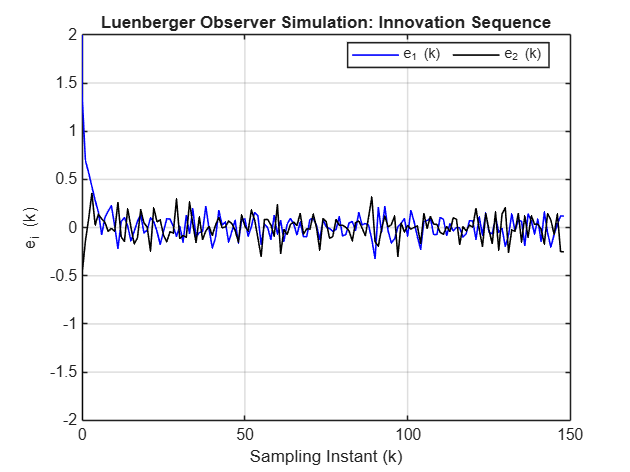

Set_Graphics_Parameters ;
figure(1), plot(kT, ek(1,:), 'b', kT, ek(2,:), 'k'), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1 (k)', 'e_2 (k)', 'Orientation','horizontal','Location','Best') 
title('Luenberger Observer Simulation: Innovation Sequence')

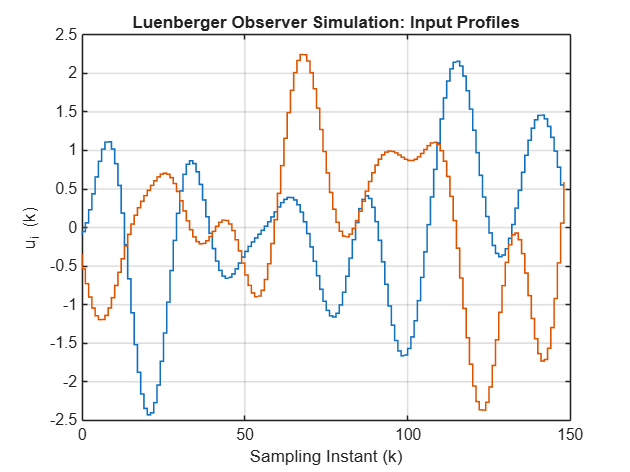

figure(2), stairs(kT, uk', 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), 
title('Luenberger Observer Simulation: Input Profiles')

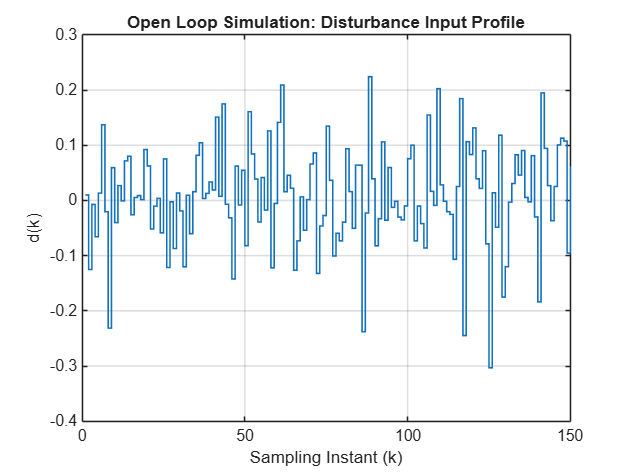

figure(3), stairs(dk, 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)'), title('Open Loop Simulation: Disturbance Input Profile')

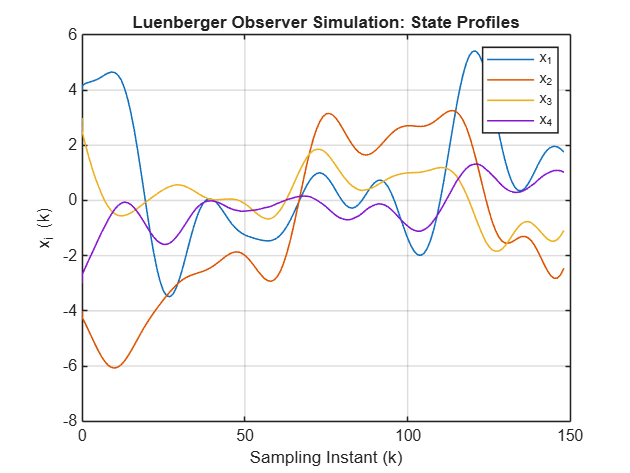

figure(4), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1', 'x_2', 'x_3', 'x_4'), 
title('Luenberger Observer Simulation: State Profiles')

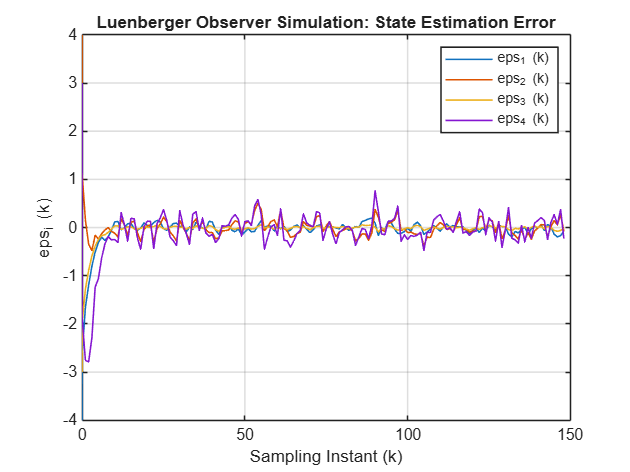

figure(5), plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('eps_i (k)')
legend('eps_1 (k)', 'eps_2 (k)', 'eps_3 (k)', 'eps_4 (k)'), 
title('Luenberger Observer Simulation: State Estimation Error')

 Note that the estimation errors have not gone to zero in the set time N=60

**Task 7:**Now increase N and observe the results again. Do the errors go to zero. Increase it further. We can see that at around N=150 all the errors go to zero. 

**Task 8: **Now set the Noise_On flag to Switch On noise. Note that the errors have increased. 

**Task 9: **Now change the estimation method to Luenberger Predictor. Note the changes in the error profiles.

**Task 10:**Try changing the pole locations for the Luenberger Predictor. Observe the responses.

**Task 11: **Repeat the exercise for Non-minimum phase operating point

It is clear from these simulations that use of a Luenberger observer with $\rho \left(\Phi -L\;C\right)\ll \rho \left(\Phi \right)$ brings estimation error to zero at a accelerated rate. Another significant advantage of using a closed loop observer is the ability to handle open loop unstable or marginally stable systems.

### Example: Reactor at Unstable Operating Point 

Now, let is look at another example: Continuous Stirred Tank Reactor (CSTR) system operated at the unstable operating point. The system dynamics are governed by the following difference equation 


$$\left\lbrack \begin{array}{c}
{\delta C}_A \left(k+1\right)\\
\delta T\left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 7943 & -0\ldotp 006245\\
11\ldotp 93 & 1\ldotp 256
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\delta C}_A \left(k\right)\\
\delta T\left(k\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0\ldotp 001006 & 0\ldotp 09613\\
-0\ldotp 3673 & -3\ldotp 612
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\delta F}_C \left(k\right)\\
\delta F\left(k\right)
\end{array}\right\rbrack$$



$$y\left(k\right)=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\delta C}_A \left(k\right)\\
\delta T\left(k\right)
\end{array}\right\rbrack$$


Here, ${\delta C}_A \;\textrm{and}\;\delta T$ represent perturbations in concentration of reactant A and temperature, respectively. Manipulated inputs,  ${\delta F}_C \;\textrm{and}\;\delta F$represent coolant flow to the cooling jacket and flow of the reactant at the reactor inlet, respectively. Only the reactor temperature is measured. 

 
clear all 

% System matrices at the unstable operating condition 
phy=[0.7943 -0.006245 ; 11.93 1.256]; 
gam=[0.001006 0.09613; -0.3673 -3.612]';
C_mat = [ 0 1] ; 


Check rank of observability matrix  

obsv_mat = obsv(phy, C_mat) 

obsv_mat =          0    1.0000
   11.9300    1.2560


rank(obsv_mat)

ans = 2

Luenberger observer design 

p1=0.6;
p2=0.5;
obs_poles = [ p1 p2 ]'; % Error Dynamics Poles 

Lp_mat = place(phy', C_mat', obs_poles)  ;
Lp_mat = Lp_mat' ; 

EigVal_CL = eig( phy -  Lp_mat * C_mat ) ; 
EigVal_CL'

ans =     0.6000    0.5000


EigVal_OL = eig(phy) ;
EigVal_OL'

ans =    1.0252 - 0.1456i   1.0252 + 0.1456i


Needless to say that the open loop observer estimation error will blow up while the closed loop observer estimator error will converge to the origin.  

## Prediction Estimator and Current State Estimator 

    Before we proceed further, we introduce an important variant of observers used in practice: filter or current state estimator. The estimator (5) that we have developed so far uses measurement obtained at instant *k * to estimate the state at time instant (*k+1*). Let is re-write it with a new notation as follows   

$\hat{x} \left(k+1|k\right)=\Phi \hat{x} \left(k|k-1\right)+\Gamma u\left(k\right)+L_p \;e\left(k\right)$  ------(19)

$e\left(k\right)=y\left(k\right)-\hat{y} \left(k|k-1\right)=y\left(k\right)-C\hat{x} \left(k|k-1\right)$  ------(20)

Here $\hat{x} \left(k+1|k\right)$ represents an estimate of the true state $x\left(k+1\right)$ using measurements up to time instant k. Since 

$\hat{x} \left(k|k-1\right)=\Phi \hat{x} \left(k-1|k-2\right)+\Gamma u\left(k-1\right)+L\;e\left(k-1\right)$   ------(21)

$e\left(k-1\right)=y\left(k-1\right)-\hat{y} \left(k-1|k-2\right)=y\left(k-1\right)-C\;x̂\left(k-1|k-2\right)$  ------(22) 

is based on measurements up to instant (k-1), we denoted it as $\hat{x} \left(k|k-1\right)$, and so on. Thus, there is a unit delay in using the measurement at instant k. A state filter, on the other hand, uses measurement at instant k for generating an estimate of the state without introducing unit delay as follows 

$\begin{array}{l}
\hat{x} \left(k|k-1\right)=\Phi \hat{x} \left(k-1|k-1\right)+\Gamma u\left(k-1\right)\\
\hat{x} \left(k|k\right)=\hat{x} \left(k|k-1\right)+L_c \;e\left(k\right)
\end{array}$ ------(23) 

The innovation is defined as equation (20). Equations (21) can be rearranged as follows 

$\begin{array}{l}
\hat{x} \left(k+1|k\right)=\Phi \hat{x} \left(k|k\right)+\Gamma u\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\Phi \left(\hat{x} \left(k|k-1\right)+L_c \;e\left(k\right)\right)+\Gamma u\left(k\right)=\Phi \hat{x} \left(k|k-1\right)+\Gamma u\left(k\right)+\Phi \;L_c \;e\left(k\right)
\end{array}$  -----(24)

Comparing equations (19) and (24), we can deduce relationship between filter and predictor gains as follows: $L_p =\Phi \;L_c$. When matrix $\Phi$ is an invertible matrix, we can compute $L_c =\Phi^{-1} \;L_p$. From equation (23), we can write 

$\varepsilon \left(k|k\right)=x\left(k\right)-\hat{x} \left(k|k\right)=x\left(k\right)-\hat{x} \left(k|k-1\right)-L_c \;e\left(k\right)=\left(I-L_c \;C\right)\left(x\left(k\right)-\hat{x} \left(k|k-1\right)\right)=\left(I-L_c \;C\right)\varepsilon \left(k|k-1\right)$  -------(25)

$\Longrightarrow \|\varepsilon \left(k|k\right)\|=\|\left(I-L_c \;C\right)\varepsilon \left(k|k-1\right)\|\le \|\left(I-L_c \;C\right)\|\|\varepsilon \left(k|k-1\right)\|$  ------(26)

Now, in the absence of state and measurement noise, the prediction error dynamics are governed by

$\varepsilon \left(k+1|k\right)=\left(\Phi -L_p \;C\right)\varepsilon \left(k|k-1\right)$  ------(27)

Since $\rho \left(\Phi -L\;C\right)<1$, it follows that $\|\varepsilon \left(k|k-1\right)\|\to 0\;\textrm{as}\;k\to \infty$ and from (24) it follows that $\|\varepsilon \left(k|k\right)\|\to 0\;\textrm{as}\;k\to \infty$

 
clear all


**Task 1: **On selecting the operating point, corresponding steady state linear discrete model and parameters will be loaded in the workspace. Specify Operating Point,  Minimum Phase or Nonminimum Phase

operating_pt=2;

% Load quadruple tank parameters and steady state The following file loads QTank data structre 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
 QTank.Q_mat=0.0025*eye(2);
end
phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = QTank.C_mat ; 

[n_st,n_ip] = size(gam);
[n_op, nx] = size(C_mat) ;
[nx, n_d] = size(gam_d)  ; 
samp_T = 4 ;  

**Task 2 :** Select the values of closed loop poles in the range 0 to 1. 

p1=0.6;
p2=0.7;
p3=0.4;
p4=0.5;
obs_poles = [ p1 p2 p3 p4]'; % Error Dynamics Poles 


Observer gain matrix Lp_mat, is obtained using **place command** in matlab. 

[**K = place(A,B,P)** ](https://in.mathworks.com/help/control/ref/place.html)computes a state-feedback matrix K such that the eigenvalues of A-B*K are those specified in the vector P.

Note that this function is written for controller design problem, i.e. placement of eigenvalues of matrix $\left(\Phi -\Gamma G\right)$ where $u\left(k\right)=-\textrm{Gx}\left(k\right)$ is a state feedback control law. Thus, to use it for observer design, we need to place eigenvalues of matrix $\left(\Phi^T -C^T {\;L}^T \right)$, which, are identical to eigenvalues of $\left(\Phi -L\;C\right)$. 

Lp_mat= place(phy', C_mat', obs_poles)  ;
Lp_mat = Lp_mat' 

Lp_mat =     1.8948         0
         0    1.1963
    4.5798         0
         0    2.6567


Lc_mat = inv( phy ) * Lp_mat   % Compute filter gain matrix 

Lc_mat =     1.5310         0
         0    1.0673
    5.0493         0
         0    2.8320


**Task 3:** Let's now see the closed loop **eigen values of (phy -  Lp_mat * C_mat )** i. e. $\Phi -L\;C$ using eig command in MATLAB and compare with open loop 

EigVal_CL = eig( phy -  Lp_mat * C_mat ) ; 
EigVal_CL'

ans =     0.4000    0.5000    0.6000    0.7000


EigVal_OL = eig(phy) ;
EigVal_OL'

ans =     0.9404    0.9600    0.9070    0.9381


**Task 4:** Simulate the observer dynamics 

N = 60 ; % Simulation run time

% Generate Input sequence 
uk1 = idinput(N,'rgs', [0,0.1]);
uk2 = idinput(N,'rgs', [0,0.1]);
uk = [ uk1' ; uk2'] ;

% Initialize matrices for saving 
xk = zeros(n_st, N) ;
yk = zeros(n_op,N) ;
xk(:,1) = [ 4 -4 3 -3]';
yk(:,1) = C_mat * xk(:,1) ;

xkhat = zeros(n_st, N) ;
xkkhat = zeros(n_st, N) ;
ykhat = zeros(n_op,N) ;
ek = zeros(n_op,N) ;

% Generate state and measurement noise sequence 
v_sigma = 0.05 ;
R_mat = v_sigma^2*eye(n_op) ;
d_sigma = 0.1 ;
Q_mat = d_sigma^2*eye(n_d)

Q_mat = 0.0100

vk = mvnrnd(zeros(n_op,1), R_mat, N) ;  % Generate measurement noise
vk = vk';
dk = mvnrnd(zeros(n_d,1), Q_mat , N) ;  % Generate state noise
dk = dk';

**Task 5:** Set the flag to **Switch ON Noise** to simulate system with noise, else set it to **Switch OFF Noise.**

NO_Noise =  0; % Set this flag for simulating system under noise free conditions 
if (NO_Noise)
    vk = 0 * vk ;  dk = 0 * dk ;  % Set state and measurement noise to zero 
end 

**Task 6: **Select type of estimator 

est_method = 1;  % Select type of estimator 
kT = zeros(N,1) ;
for k = 1 : N-1
    kT(k+1) = (k-1) ;

    % Simulate observer dynamics from k to k+1
    
   if (est_method ==1 )
        % Luenberger predictor 
         ykhat(:,k) = C_mat * xkhat(:,k) ; 
         ek(:,k) = yk(:,k) - ykhat(:,k) ;
        xkhat(:,k+1)= phy * xkhat(:,k) + gam * uk(:,k) + Lp_mat * ek(:,k) ;
    else
        % Current state observer
        if (k>=2)
            xkhat(:,k) = phy * xkkhat(:,k-1) + gam * uk(:,k-1) ;
            ykhat(:,k) = C_mat * xkhat(:,k) ; 
            ek(:,k) = yk(:,k) - ykhat(:,k) ; 
            xkkhat(:,k)= xkhat(:,k) + Lc_mat * ek(:,k) ;
        end
    end

    ykhat(:,k+1) = C_mat * xkhat(:,k+1) ; 

    % Simulate plant dynamics from k to k+1 
    xk(:,k+1)= phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1) ; 
end
ek(:,N) = ek(:,N-1) ; 

if ( est_method ==1 )
    est_err = xkhat - xk ;  % State estimation error
else
    k = N ; 
    xkhat(:,k) = phy * xkkhat(:,k-1) + gam * uk(:,k-1) ;
    ykhat(:,k) = C_mat * xkhat(:,k) ;
    ek(:,k) = yk(:,k) - ykhat(:,k) ;
    xkkhat(:,k)= xkhat(:,k) + Lc_mat * ek(:,k) ;
    est_err = xkkhat - xk ;  % State estimation error
end

**Display Simulation Results**

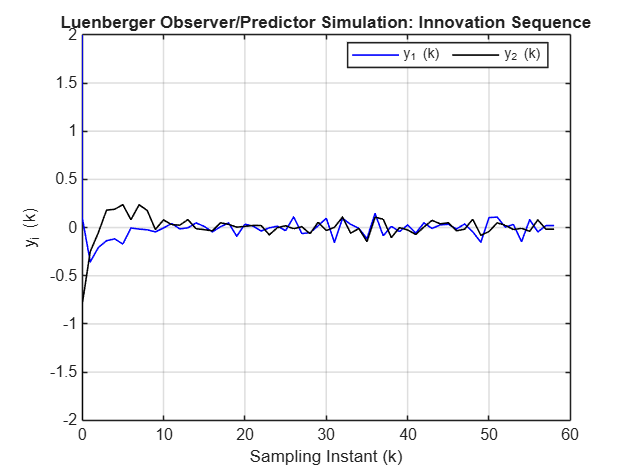

Set_Graphics_Parameters ;
figure(1), plot(kT, ek(1,:), 'b', kT, ek(2,:), 'k'), grid
xlabel('Sampling Instant (k)'), ylabel('y_i (k)')
legend('y_1 (k)', 'y_2 (k)', 'Orientation','horizontal','Location','Best') 
title('Luenberger Observer/Predictor Simulation: Innovation Sequence')

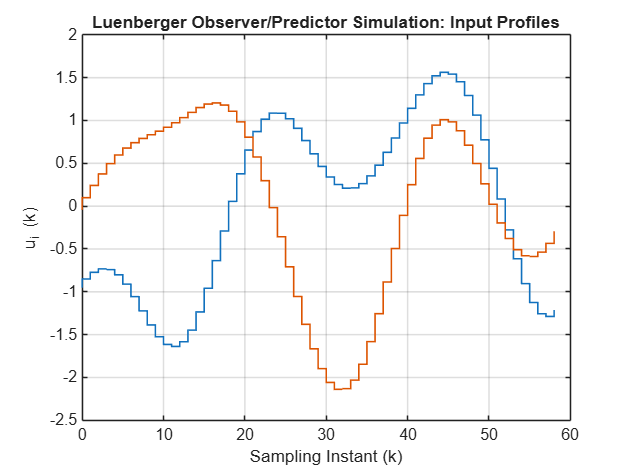

figure(2), stairs(kT, uk', 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), 
title('Luenberger Observer/Predictor Simulation: Input Profiles')

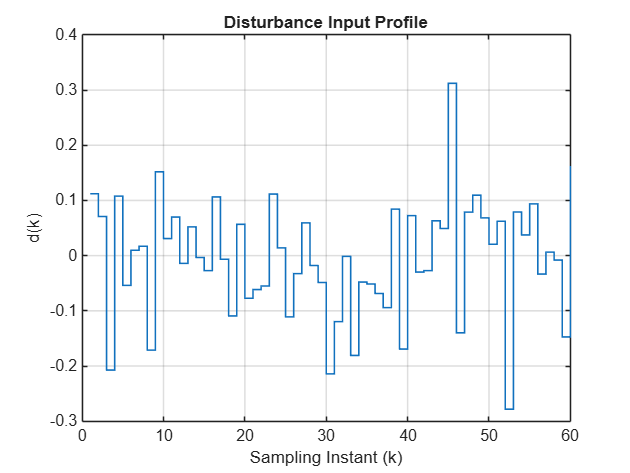

figure(3), stairs(dk, 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)'), title('Disturbance Input Profile')

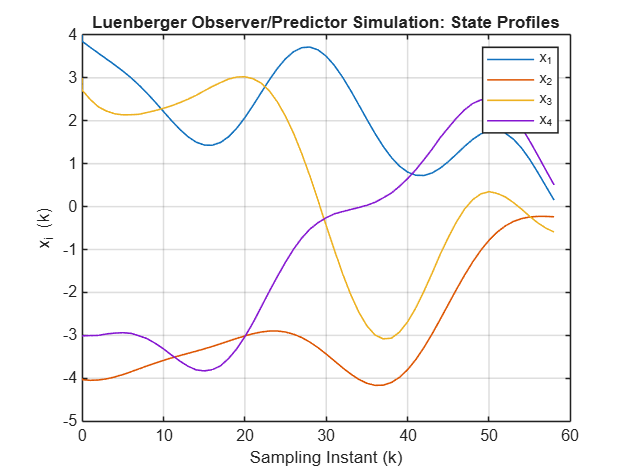

figure(4), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1', 'x_2', 'x_3', 'x_4'), 
title('Luenberger Observer/Predictor Simulation: State Profiles')

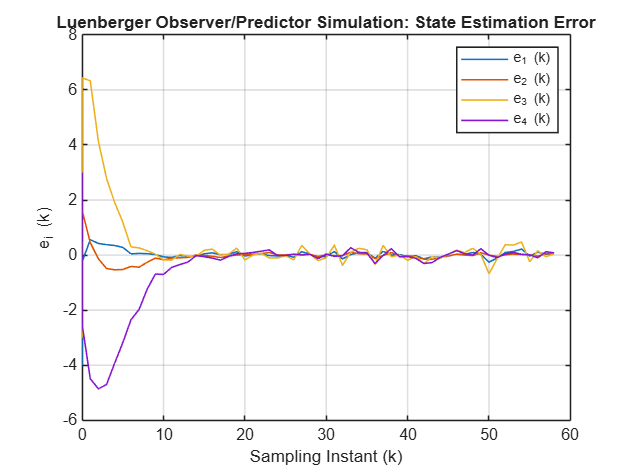

figure(5), plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1 (k)', 'e_2 (k)', 'e_3 (k)', 'e_4 (k)'), 
title('Luenberger Observer/Predictor Simulation: State Estimation Error')

It is difficult to notice difference between the filtered and predicted estimation errors. However, from the viewpoint on online computations, current state estimator computations have to be carried out before controller implementation and the prediction estimator calculations have to be carried out after the controller calculations. In an application involving very short sampling intervals, it is desirable to use the prediction estimator. 

## **Conclusion**

In this lesson, we have seen the operation of Open Loop and Closed Loop observers. Development of Luenberger Observer (1961) by pole placement is a major corner stones in the history of state estimation. While many algorithms are available for pole placement of multiple output systems**, for a large dimensional system it is difficult to choose poles such that the desired estimation performance is achieved in the face of uncertainties in the state dynamics and measurement errors. ** This difficulty is alleviated by another seminal contribution to state estimation area: Kalman filtering.  We will learn about [Kalman Filter](matlab:open('./L03_Stochastic_Inputs_and_Kalman_Filtering.mlx')) in the next lesson. 

## References

Astrom, K. J. and B. Wittenmark, Computer Controlled Systems, Prentice Hall, 1990.

Franklin, G. F. and J. D. Powell, Digital Control of Dynamic Systems, Addison-Wesley, 1989.

Goodwin, G., Graebe, S. F., Salgado, M. E., Control System Design, PHI Learning, 2009.

Fadali, M. S. And Visioli, A., Digital Control Engineering: Analysis and Design, Academic Press, 2019. 

## Appendix: Pole Placement Controller Design

In this Appendix we describe how to design a pole placement controller. At the end of the lesson, we explain how these techniques can be used for observer design. 

Let the *true process or system dynamics* be given as,


$$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$$



$$y\left(k\right)=\textrm{Cx}\left(k\right)\;\;\textrm{with}\;x\left(0\right)\not= \bar{0}$$


It is assumed that the states are perfectly measured. The regulatory control problem is to bring the system to the origin using a state feedback control law 


$$u\left(k\right)=-\textrm{Gx}\left(k\right)$$


Then the closed loop dynamics is governed by 


$$x\left(\textrm{𝑘}+1\right)=\Phi x\left(\textrm{𝑘}\right)+\Gamma u\left(\textrm{𝑘}\right)=\left(\Phi -\Gamma G\right)x\left(\textrm{𝑘}\right)$$


We have to choose controller gain matrix **G **such that the closed loop system is stable and the state reaches the origin the origin as quickly as possible. Choose controller G gain such that

 
$$\max_i \left|\lambda_i \left(\Phi -\Gamma G\right)\right|<1$$


where $\lambda_i$ is the $i^{\textrm{th}\;}$ eigenvalue of $\left(\Phi -\Gamma G\right)$.  The above choice ensure that $\left\|x\left(k\right)\right\|\to 0$ as  $k\to \infty$ and  ${\left(\Phi -\Gamma G\right)}^k \to$Null Matrix as $k\to \infty$ irrespective of choice of $x\left(0\right)$. 

**Single Input System: Pole Placement Design **

 As a simple motivating example, consider a CSTR model with 

$\Phi =\left\lbrack \begin{array}{cc}
0\ldotp 185 & -0\ldotp 01\\
73\ldotp 49 & 1\ldotp 33\;
\end{array}\right\rbrack$and $\Gamma =\left\lbrack \begin{array}{c}
0\ldotp 0026\\
-0\ldotp 7335
\end{array}\right\rbrack$

Let the controller gain be parameterized as  $G=\left\lbrack \begin{array}{cc}
a & b
\end{array}\right\rbrack$, which implies 


$$\Phi -\Gamma G=\left\lbrack \begin{array}{cc}
0\ldotp 185-0\ldotp 0026a & -0\ldotp 01-0\ldotp 0026b\\
73\ldotp 49+0\ldotp 7335a & 1\ldotp 33+0\ldotp 7335b
\end{array}\right\rbrack$$


The characteristic equation for $\Phi -\Gamma G$ is


$$\begin{array}{l}
\det \left\lbrack \lambda I-\left(\Phi -\Gamma G\right)\right\rbrack =\left(\textrm{𝜆}-0\ldotp 185+0\ldotp 0026a\right)\left(\textrm{𝜆}-\left(1\ldotp 33+0\ldotp 7335b\right)\right)+\left(73\ldotp 49+0\ldotp 7335a\right)\left(0\ldotp 01+0\ldotp 0026b\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\lambda^2 -\left(1\ldotp 515+0\ldotp 0026a-0\ldotp 7335b\right)\lambda +\left(0\ldotp 007335a+0\ldotp 1911b+0\ldotp 7349\right)
\end{array}$$


**Pole Placement Design: **Suppose we want to ′place′ poles of  $\Phi -\Gamma G$ at  $\lambda_1 =0\ldotp 5,\lambda_2 =0\ldotp 25$ i.e. desired characteristic polynomial of $\Phi -\Gamma G$  is 


$$\left(\lambda -0\ldotp 5\right)\left(\lambda -0\ldotp 25\right)=\lambda^2 -0\ldotp 75\lambda +0\ldotp 125$$


Comparing coefficients of characteristic polynomials, the poles can be placed at the desired location if we select $\left(a,b\right)$ such that 


$$1\ldotp 515+0\ldotp 0026a-0\ldotp 7335b=0\ldotp 75$$



$$0\ldotp 007335a+0\ldotp 1911b+0\ldotp 7349=0\ldotp 125$$


or using matrix notation 


$$\left\lbrack \begin{array}{cc}
0\ldotp 0026 & -0\ldotp 7335\\
0\ldotp 007335 & 0\ldotp 1911
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 75-1\ldotp 515\\
0\ldotp 125-0\ldotp 7349
\end{array}\right\rbrack$$


i.e. when $a=????\;\textrm{and}\;b=????$. A difficulty with** t**his ‘***raw approach***’ of placing poles becomes cumbersome to use for systems of higher dimension. Moreover, this raw approach works only for single input systems.  To understand difficulty in dealing with multiple input system, consider the CSTR system with two manipulated inputs (coolant flow and reactor inlet flow) 

$\Phi =\left\lbrack \begin{array}{cc}
0\ldotp 185 & -0\ldotp 01\\
73\ldotp 49 & 1\ldotp 33\;
\end{array}\right\rbrack$and $\Gamma =\left\lbrack \begin{array}{cc}
0\ldotp 0026 & 0\ldotp 13\\
-0\ldotp 7335 & -0\ldotp 18
\end{array}\right\rbrack$

Since two manipulated inputs are available, the $G$ matrix is of the form 


$$G=\left\lbrack \begin{array}{cc}
\alpha  & \beta \\
\gamma  & \delta 
\end{array}\right\rbrack$$



$$\Phi -\Gamma G=\left\lbrack \begin{array}{cc}
0\ldotp 185 & -0\ldotp 01\\
73\ldotp 49 & 1\ldotp 33\;
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
0\ldotp 0026 & 0\ldotp 13\\
-0\ldotp 7335 & -0\ldotp 18
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\alpha  & \beta \\
\gamma  & \delta 
\end{array}\right\rbrack$$


$\det \left\lbrack \lambda I-\Phi -\Gamma G\right\rbrack$is a function of $\left(\alpha ,\beta ,\gamma ,\delta \right)$.  Comparing coefficients with $\lambda^2 +p_1 \lambda +p_2$ yields only 2 equations in 4 unknowns. It means there is no unique solution to the design problem.  

**Multiple Input System: Pole Placement Design **

Consider a MIMO system with  $u\in R^m$


$$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$$
 

With state feedback controller  law 


$$u\left(k\right)=-\textrm{Gx}\left(k\right)$$


where $G$ is a  $\left(m\times n\right)$ matrix. The closed loop dynamics is governed by

 
$$\textrm{𝐱}\left(\textrm{𝑘}+1\right)=\Phi \textrm{𝐱}\left(\textrm{𝑘}\right)+\Gamma \textrm{𝐮}\left(\textrm{𝑘}\right)=\left(\Phi -\Gamma \textrm{𝐆}\right)\textrm{𝐱}\left(\textrm{𝑘}\right)$$


If we intend to place poles of closed loop  at the roots of 


$$\lambda^n +p_1 \lambda^{n-1} +\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +p_n =0$$


then equating coefficients of  $\det \left\lbrack \lambda I-\left(\Phi -\Gamma G\right)\right\rbrack =0$ with the desired closed loop polynomial gives only $n$ equations.  However, the number of unknowns equals $\left(n\times m\right)$ elements of $G$. Thus, we have an under-determined system of equations. Hence additional constraints need to be imposed to solve pole placement problem and there are multiple ways available in the literature to include the additional constraints. The following theorem presents one such approach. 

**Throrem (Fadali and Visioli, 2019):** For any controllable pair $\left(\Phi ,\Gamma \right)$,  there exists a state feedback matrix $G$ that assigns the eigenpairs$\left(\lambda_i ,v_{\textrm{cl}}^{\left(i\right)} \right)$for $i=1,2,\ldotp \ldotp \ldotp ,n$ if and only if


$$\left.{\textrm{𝐔}}_1^T \left(\textrm{𝚽}-\lambda_i I_{\left(n\times n\right)} \right)v_{\textrm{cl}}^{\left(i\right)} ={\bar{0} }_{\left(n\times 1\right)} \right)$$


where $\Gamma =U\left\lbrack \begin{array}{c}
{\left\lbrack \Sigma_{\Gamma } \right\rbrack }_{m\times m} \\
{\left\lbrack 0\right\rbrack }_{\left(n-m\right)\times m} 
\end{array}\right\rbrack V^T =U\left\lbrack \begin{array}{c}
Z_{m\times m} \\
{\left\lbrack 0\right\rbrack }_{\left(n-m\right)\times m} 
\end{array}\right\rbrack$ represents the singular value decomposition of $\Gamma$with

$\textrm{𝐔}=\left\lbrack \left(\underset{\textrm{𝑛}\times \textrm{𝑚}}{\underbrace{U_0 } } \right)\left(\underset{\textrm{𝑛}\times \left(n-\textrm{𝑚}\right)}{\underbrace{U_1 } } \right)\right\rbrack$ and $U^T =U^{-1}$

The state feedback gain is given by


$$\textrm{𝐆}=-{\textrm{𝐙}}^{-1} {{\textrm{𝐔}}_0 }^T \left\lbrack {\textrm{𝐕}}_{\textrm{cl}} \Lambda_{\textrm{cl}} {{\textrm{𝐕}}_{\textrm{cl}} }^{-1} -\textrm{𝚽}\right\rbrack$$


${\textrm{𝐕}}_{\textrm{cl}} =\left\lbrack \begin{array}{cccc}
v_{\textrm{cl}}^{\left(1\right)}  & v_{\textrm{cl}}^{\left(2\right)}  & \cdots  & v_{\textrm{cl}}^{\left(n\right)} 
\end{array}\right\rbrack$and  


$$\Lambda_{\textrm{cl}} =\textrm{diag}\left\lbrack \begin{array}{cccc}
\lambda_1  & \lambda_2  & \cdots  & \lambda_n 
\end{array}\right\rbrack$$


We present an illustrative example from **Fadali and Visioli (2019) **to illustrate this method. Consider a system


$$\textrm{𝚽}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-0\ldotp 005 & -0\ldotp 11 & -0\ldotp 7
\end{array}\right\rbrack$$
 
$$\Gamma =\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 1\\
1 & 1
\end{array}\right\rbrack$$



$$\Gamma =\left\lbrack \underset{U_0 }{\underbrace{\left\lbrack \begin{array}{cc}
-0\ldotp 5000 & -0\ldotp 5000\\
-0\ldotp 5000 & -0\ldotp 5000\\
-0\ldotp 7071 & 0\ldotp 7071
\end{array}\right\rbrack } } \;\underset{U_1 }{\underbrace{\left\lbrack \begin{array}{c}
-0\ldotp 7071\\
0\ldotp 7071\\
0
\end{array}\right\rbrack } } \right\rbrack \left\lbrack \begin{array}{c}
\underset{\sum \Gamma }{\underbrace{\left\lbrack \begin{array}{cc}
1\ldotp 8478 & 0\\
0 & 0\ldotp 7654
\end{array}\right\rbrack } } \\
\left\lbrack \begin{array}{cc}
0 & 0
\end{array}\right\rbrack 
\end{array}\right\rbrack \underset{V^T }{\underbrace{\left\lbrack \begin{array}{cc}
-0\ldotp 3827 & 0\ldotp 9239\\
-0\ldotp 9239 & 0\ldotp 3827
\end{array}\right\rbrack } }$$


**Desired closed-loop eigenvalues:**$\lambda_1 =0\ldotp 1,\lambda_2 =0\ldotp 2,\lambda_3 =0\ldotp 3$

For the eigenvalue $\lambda_1 =0\ldotp 1$

${U_1 }^T \left(\textrm{𝚽}-0\ldotp 1I_{\left(3\times 3\right)} \right)v_{\textrm{cl}}^{\left(1\right)} =\left\lbrack 0\ldotp 0707\;-0\ldotp 7778\;\;0\ldotp 7071\right\rbrack v_{\textrm{cl}}^{\left(1\right)} ={\bar{0} }_{n\times 1}$ gives


$$v_{\textrm{cl}}^{\left(1\right)} ={\left\lbrack 0\ldotp 7383\;0\ldotp 4892\;0\ldotp 4643\right\rbrack }^T$$



$${\textrm{𝐕}}_{\textrm{cl}} =\left\lbrack \begin{array}{ccc}
0\ldotp 7383 & 0\ldotp 4892 & 0\ldotp 4643\\
0\ldotp 4892 & 0\ldotp 4848 & 0\ldotp 4848\\
0\ldotp 4643 & 0\ldotp 4293 & 0\ldotp 3963
\end{array}\right\rbrack =\textrm{diag}\left\lbrack \begin{array}{ccc}
0\ldotp 1 & 0\ldotp 2 & 0\ldotp 3
\end{array}\right\rbrack$$
       


$$\begin{array}{l}
\Phi_{\textrm{cl}} =\left(\Phi -\Gamma \textrm{𝐆}\right)={\textrm{𝐕}}_{\textrm{cl}} \Lambda_{\textrm{cl}} {{\textrm{𝐕}}_{\textrm{cl}} }^{-1} \\
=\left\lbrack \begin{array}{ccc}
0\ldotp 2377 & 2\ldotp 0136 & -2\ldotp 3405\\
0\ldotp 2377 & 1\ldotp 0136 & -1\ldotp 3405\\
0\ldotp 6511 & -0\ldotp 2695 & -0\ldotp 6513
\end{array}\right\rbrack 
\end{array}$$



$$Z=\Sigma_{\Gamma } V=\left\lbrack \begin{array}{cc}
-0\ldotp 7071 & -1\ldotp 7071\\
0\ldotp 7071 & -0\ldotp 2929\\
0 & 0
\end{array}\right\rbrack$$



$$\begin{array}{l}
\textrm{𝐆}=-{\textrm{𝐙}}^{-1} {{\textrm{𝐔}}_0 }^T \left\lbrack {\textrm{𝐕}}_{\textrm{cl}} \Lambda_{\textrm{cl}} {{\textrm{𝐕}}_{\textrm{cl}} }^{-1} -\textrm{𝚽}\right\rbrack \\
=\left\lbrack \begin{array}{ccc}
-0\ldotp 4184 & 1\ldotp 1730 & -2\ldotp 3892\\
-0\ldotp 2377 & -1\ldotp 0136 & 2\ldotp 3405
\end{array}\right\rbrack 
\end{array}$$


**Note****: **Since number of variables exceeds the number of equations, additional constrains have been included to arrive at a matrix G that places closed loop poles at the desired location. This solution is not unique. Imposing different constraints will change the G matrix while placing the closed loop poles at the identical location. 

MATLAB command** ′place′** gives the following gain matrix 


$$G\;=\left\lbrack \begin{array}{ccc}
-0\ldotp 0346 & 0\ldotp 3207 & -2\ldotp 0996\\
-0\ldotp 0499 & 0\ldotp 0852 & 0\ldotp 7642
\end{array}\right\rbrack$$


but with a different choice of eigenvectors of$\left(\Phi -\Gamma G\right)$. 

   The `place` function in MATLAB Control System Toolbox is meant for placing poles of $\left(\Phi -\Gamma G\right)$, i.e. for designing a state feedback controller by pole placement. How do we use this controller pole placement function to place poles of a Luenberger observer? Note that in observer design, we are interested in the stability of the observer error dynamics, i.e. 


$$\varepsilon \left(k+1\right)=\left(\Phi -L\;C\right)\varepsilon \left(k\right)$$
 

If we compare how unknown matrices G and L appear in the respective closed loop matrices then, it can be observed that  matrix$\left(\Phi^T -C^T \;L^T \right)$ is similar to $\left(\Phi -\Gamma G\right)$. Thus, if we carry out pole placement by replacing $\Phi$ by $\Phi^T$  and $\Gamma$ by $C^T$, then the resulting gain matrix after pole placement is nothing but $\;L^T$. This trick works because the eigenvalues of a matrix and its transpose are identical. 